# RBE 501: Path Planning Nuro Project

Sean Tseng, Debbie G, Lucas Vanslette

## Initialize Occupancy Map

This section loads the road map that the robot will be navigating in this project. The first step is to binarize the road map imagine. Road map is still in progress, replace the name in 'imread' to read in a different image for path planning.

Dubins explanation: [https://demonstrations.wolfram.com/IsochronsForADubinsCar/](https://demonstrations.wolfram.com/IsochronsForADubinsCar/)

clear
clc
J = imread('Map_Version5.jpg');
% change so that all pixels less than 240 are all now 0 (all black)
J(J < 240) = 0;
J(J >= 240) = 255;
J = J(:,:,1);
resize_fac =10;
map = binaryOccupancyMap(J,resize_fac);
show(map)
title('Test Image for Project')
xlabel('X')
ylabel('Y')
grid on
hold on

## Initialize Simulation Parameters

Update state space bounds to be the same as map limits, which were generated earlier with the binaryOccupancyMap method. Also, create a Dubins model of the vehicle with bounds imported from the occupancy map.

bounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];
ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.05;

Create a state validator using the created state space and based on the occupancy map created from the png image.

sv = validatorOccupancyMap(ss);
sv.Map = map;

Set validation distance for the simulation.

sv.ValidationDistance = 0.02;

Now the planner can be created with a modifiable maximum distance between nodes of the tree.

Maxdistance = 0.4;

Establish start and goal states. If start and/or goal position are impossible, then system throws error. 

wayP = 3;

Enter the weight of the groceries, in pounds

% added total grocery weight as a parameter
weight = "40";
% added car type to determine waypoints
carType = "Nuro"

carType = "Nuro"

switch carType
    case "Nuro"
        carCapacity = 5;
    case "RAM"
        carCapacity = 10;
end

Calculate the random waypoints that the car will traverse

[distance, waypoints] = calculate_waypoints(map, wayP, carType, carCapacity);

waypoints =    91.0000   84.0000   60.0000
   44.0000   20.0000   24.0000
    4.5000    1.0000    1.0000


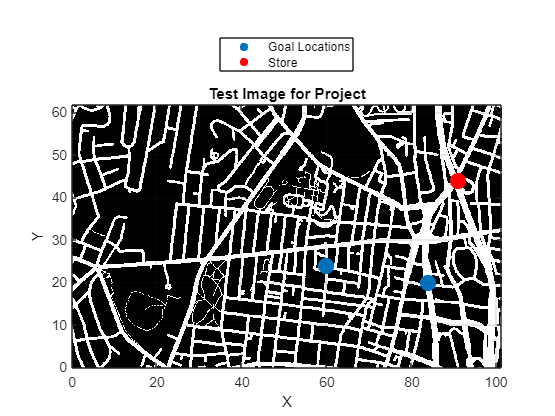

hold off

algorithm = 3;

**Start simulation**

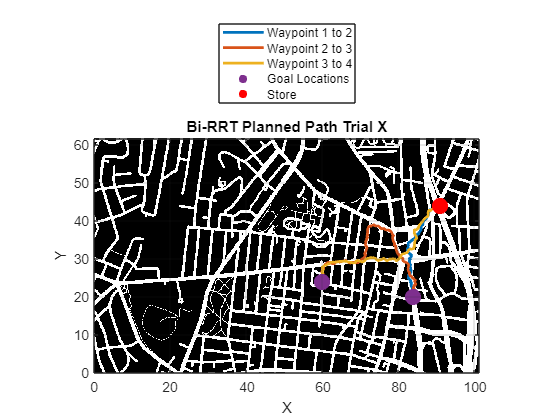

avg_MA_carbon = 1.3508e+06

nuro_carbon = 188.5655

14.0172 km traveled
Total emissions from simulation (kilograms carbon): 6711.51245      9261.28812      10458.8107


% added function that runs below simulation X times
%simulation(map, algorithm, waypoints, ss, sv, Maxdistance)
simulation(map, algorithm, waypoints, ss, sv, Maxdistance);

**Function calculate_waypoints: given car, calculate all places that the car will stop on its route**

function [distance, waypoints] = calculate_waypoints(map, num_waypoints, carType, carCapacity)


    % added num_refills, which is the minimum number of times Nuro would have
    %   to go back to the start and refill its capacity for groceries

    
    % waypoints = [  x1     x2   ...
    %                y1     y2   ...
    %              theta1 theta2 ... ]
    % % test case
    % waypoints = [91  84 60;   %x
    %              44  20 24;   %y
    %              4.5 1  1 ; ] %theta

    
    for i=1:num_waypoints
        % generate random waypoints
        rand_theta = -5 + (5+5)*rand(1,1);
        rand_x = 
        wpt = [rand_x; rand_y; rand_theta;];

    % check their validity in the map

    % save as a new waypoint


    % plot waypoints in BIG lettering
    % scatter(x,y,sz,symbol,'filled')
    scatter(waypoints(1, 2:end), waypoints(2, 2:end), 140, 'filled');
    % plot the first waypoint (the store) in a different way
    scatter(waypoints(1,1), waypoints(2,1), 140, 'r', 'filled');
    legend('Goal Locations', 'Store', 'Location', 'northoutside');

    % first row in waypoints is the store, add it to the end of the list of waypoints
    waypoints(:, end+1) = waypoints(:,1);
    
    distance = zeros(1,wayP);
end

function simulation(map, algorithm, waypoints, ss, sv, Maxdistance)

## User Defined Path Planning

Choose what planning algorithm to use, options include RRT, RRT*, Bidirectional RRT, Hybrid A*, A* from the drop down menu. The A* algorithm only accepts a 2x1 vector instead of a 3x1 vector like the other algorithms.

choose = algorithm;
    switch choose
        case 1
            planner = plannerRRT(ss,sv,MaxConnectionDistance=Maxdistance);
        case 2
            planner = plannerRRTStar(ss,sv,MaxConnectionDistance=Maxdistance);
        case 3
            planner = plannerBiRRT(ss,sv,MaxConnectionDistance=Maxdistance);
    end
planner.MaxIterations = 100000;

## Plotting Results

If the user wants to select the option to see the whole tree expansion or not in the dropdown below.

plot_choose = false;

Enter the number of waypoints for the simulation

% changed to add waypoints based on number of inputted waypoints
wayP = length(waypoints);
%wayP = 3;

### RRT and RRT* Plot

This else condition is for the RRT and RRT* algorithms, the plan function creates plan based on the  arguments inputed into the function. Most of the path planning algorithms are plotted the same way, but the RRT algorithms are more complex than that of the A* derivatives.

All path planning algorithms must create a plan using the plan function, which takes the planner object created in the **'User Defined Path Planning Section'**. This returns a navPath object and a data structure called 'solnInfo' used for plotting.

if choose == 1 || choose == 2

The results are then collected and presented in graphical form. For RRT based algorithms, the tree must iterated over and each node fed into the plot graph from the data structure object called solnInfo. Then the path is drawn using data from the navPath object.

show(map)
    % Must always change the title in this section here
string_title = "RRT* Planned Path";
title(string_title)
xlabel('X')
ylabel('Y')
grid on
hold on

The for loop is for iterating through the entire set of waypoints that the user has given.

for i =1:wayP-1
    start = waypoints(:,i)';
    goal = waypoints(:,i+1)';

    [pthObj,~] = plan(planner,start,goal);
    path=plan(planner,start,goal);

The path length is found using the function pathLength, this will be used to determine the emission of the vehicle's path.

    distance(1,i)=pathLength(path);

If the user wants to plot the whole tree expansion, the if condition will read true and the code to plot the expansion will execute, otherwise only the planned path will be plotted.

    % if plot_choose ==true
    %     % Tree expansion
    %     plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-')
    % end

    % Draw path for this waypoint path
    plot(pthObj.States(:,1),pthObj.States(:,2),'-','LineWidth',2)
    legend_plots{i} = sprintf('Waypoint %i to %i', i, i+1);
end

List the final coordinates of the robot.

% disp(pthObj.States(end,1))
% disp(pthObj.States(end,2))
% disp(pthObj.States(end,3))

### Bidirectional RRT Plot

[https://ieeexplore.ieee.org/document/9638379](https://ieeexplore.ieee.org/document/9638379)

This section is for plotting the results from Bidirectional RRT algorithm. The code is generally the same as that of RRT and RRT*, but there are 2 tree expansions, one for the forward tree, and one for the backwards tree. When these two trees meet each other, the backward tree will act as a heuristic to guide the forward tree to continuously grow toward the goal state, where the algorithm switches to unidirectional search mode. 

elseif choose == 3

There is also an option here to enable connect heuristic for the planner object.

show(map)
string_title = "Bi-RRT Planned Path Trial X";
title(string_title)
xlabel('X')
ylabel('Y')
grid on
hold on

planner.EnableConnectHeuristic = false;
% for each waypoint
for i =1:wayP-1
    start = waypoints(:,i)';
    goal = waypoints(:,i+1)';

    [pthObj,~] = plan(planner,start,goal);
    path = plan(planner,start,goal);
    distance(1,i)=pathLength(path);
    

Now the tree expansion can be drawn, if the user selected to show all tree expansions, the if condition will be read as true, otherwise only the optimized path will be drawn.

    % Start tree expansion
    % if plot_choose == true
    % plot(solnInfo.StartTreeData(:,1),solnInfo.StartTreeData(:,2), ...
    %     '.-','color','b')
    % % Goal tree expansion
    % plot(solnInfo.GoalTreeData(:,1),solnInfo.GoalTreeData(:,2), ...
    %     '.-','color','g')
    % end

    % Draw path
    plot(pthObj.States(:,1),pthObj.States(:,2),'-','LineWidth',2);
    legend_plots{i} = sprintf('Waypoint %i to %i', i, i+1);
end

end planning algorithm

end

% plot waypoints in BIG lettering
% scatter(x,y,sz,symbol,'filled')
scatter(waypoints(1, 2:end), waypoints(2, 2:end), 140, 'filled');
% plot the first waypoint (the store) in a different way
scatter(waypoints(1,1), waypoints(2,1), 140, 'r', 'filled');
legend_plots{end+1} = 'Goal Locations';
legend_plots{end+1} = 'Store';
legend(legend_plots, 'Location', 'northoutside');
hold off

## Calculating Nuro Vehicle Emissions

This section will be for calculating the emission of the vehicle. The Nuro autonomous vehicle has the following stats:

source: [https://www.sciencedirect.com/science/article/pii/S1361920920306301?casa_token=4RF5gYc7sf0AAAAA:7oqllUDzDqQI1obliIZy6W-ZWc2Pb8iyKLOGftvfJhuyTarsgXleM2OWCz4InrdWO_vEl0Nyhw](https://www.sciencedirect.com/science/article/pii/S1361920920306301?casa_token=4RF5gYc7sf0AAAAA:7oqllUDzDqQI1obliIZy6W-ZWc2Pb8iyKLOGftvfJhuyTarsgXleM2OWCz4InrdWO_vEl0Nyhw)

- Payload = 110 kg

- range = 16.1 km

- Energy consumption = 139.6 wh/km

Factoring in energy production for the state of MA:

[https://www.eia.gov/state/?sid=MA#tabs-4](https://www.eia.gov/state/?sid=MA#tabs-4)

Dec 2022:

- Petroleum-Fired = 8.9%, 180,000 MWh

- Natural Gas Fired = 73.9%  1,492,000 MWh

- Coal Fired = 0.0%

- Nuclear = 0%

- Renewables = 15% 303,000 MWh

[https://www.forestresearch.gov.uk/tools-and-resources/fthr/biomass-energy-resources/reference-biomass/facts-figures/carbon-emissions-of-different-fuels/](https://www.forestresearch.gov.uk/tools-and-resources/fthr/biomass-energy-resources/reference-biomass/facts-figures/carbon-emissions-of-different-fuels/)

Assessing and averaging total carbon emission of MA. Natural gas is 202 kg/Mwh, Petroleum is 260 kg/MWh. Therefore MA carbon emission stands at 348,184,000 kg CO_2 in December.

%Find weighted average 
p_carbon = 180000;
gas_carbon = 1492000;
carbon_energy = p_carbon + gas_carbon;
p_weight = p_carbon/carbon_energy;
gas_weight = gas_carbon/carbon_energy;

This weighted average calculates the actual MA carbon emission as kg CO2 per MWh of carbon based fuel burned. 

%Employ formula
avg_MA_carbon= p_weight*p_carbon+gas_weight*gas_carbon

Now using information from Nuro, convert the kg/MWh of the MA electric grid to kg/wh and then multiply that by the Nuro's wh/km to get the average kg CO2 per km of the Nuro vehicle, which is the following:

nuro_carbon = avg_MA_carbon/1000000*139.6

Now the total distance traveled will be multiplied by Nuro's carbon footprint per kilometer to yield the total emissions for the trip.

%calculating emissions (just placeholder sample) change the the calculation
%to actual emissions data
total_distance = sum(distance,'all')*.1; %to get km from hectometer --> need to change  
disp(append(num2str(total_distance),' km traveled'))
emiss = distance*nuro_carbon;
disp(append('Total emissions from simulation (kilograms carbon): ',num2str(emiss)));

end